% Getting topox and topoy and threshold files, re-sizing them

% (navigate to ball data folder, then to to diff folder to 
% save figs/vars at end)

addpath F:\Kristen\Widefield2\041121_G6H277RT_RIG2\balldata_G6H277RT

close all
clear all

% load SUBJ mat file: 

load('G6H277RT_subj.mat')
% load('EE81LT_subj.mat')

% load SESSIONS mat file:
% doBehavior generates one of these files per session:

load('20210411T123140_25.mat') % 277RT 041121

% load('20210410T195352_20.mat') % 277RT 041021

% load('20210406T144122_9.mat') % EE81LT 040621

% load('20210405T132423_8.mat') % EE81LT 040421 the real date is 4/5 but says 4/4 on file name

%load('20210402T161748_7.mat') % EE81LT 040221 
% now this one is in the EE81LT folder 
% for 4-4 and has the most trials - 656

% % load('20210402T133555_14.mat') % inside 277RT 040221
% % at first I thought misnamed EE81LT 040221's missing ball data from 
% % 4/2 was here, in the 277RT balldata folder from 4-2
% % but, while it has the correct (newest) duration settings
% % it only has but 229 trials

% load('20210305T150519_3.mat') % 277RT 030521

% load('20210311T161951_5.mat') % 277RT 031121
% OR:
% load('20210311T154010_4.mat') % 277RT 031121 - this is the last session that day so maybe the correct one? I think I deleted the previous imaging session just because eye cam didnt work?

% load('20210204T164434_3.mat') % EE1LT 020421
% load('20210204T131006_5.mat') % 277RT 020421

% load('20210107T155415_1.mat') % 277RT 010721
% load('20210107T140819_6.mat') % EE81LT 010721 (file acccidentally named 010621)


[f p] = uigetfile('*.mat','topox maps file')
load(fullfile(p,f),'mapNorm');
topox = polarMap(mapNorm{3}); % polar map = projecting features from plane to sphere
f1 = figure
imshow(topox)
title('topox polar map of normalized WF signal')

% savefig('EE8LT_020421_topoX_retinotopy_imThreshPass') % hard coding

[f p] = uigetfile('*.mat','topoy maps file')
load(fullfile(p,f),'mapNorm','map');
topoy = polarMap(mapNorm{3});
f2 = figure
imshow(topoy)
title('topoy polar map of normalized WF signal')

[f p] = uigetfile('*.mat','maps file');

downsize = 0.25; % why resize by this factor?
load(fullfile(p,f));
df = imresize(dfof_bg,downsize);
topox = imresize(topox,downsize);
topoy = imresize(topoy,downsize);


%save('041121_277RT_imThressPass1stVars.mat','-v7.3')

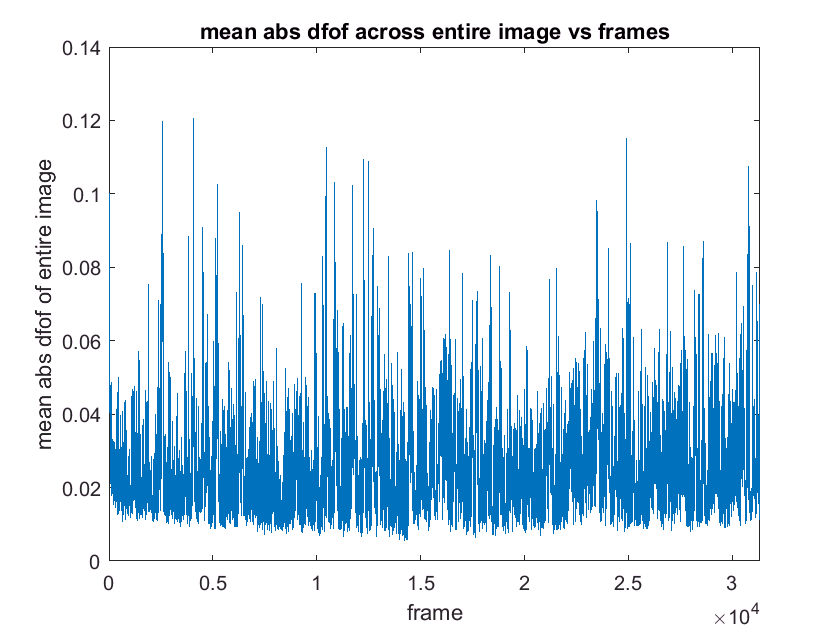

% taking the average of the entire imaging field over time
mn = mean(mean(abs(df),2),1); 

figure
plot(squeeze(mn)); title('mean abs dfof across entire image vs frames'); 
ylabel('mean abs dfof of entire image') 
xlabel('frame') 
xlim([0 size(squeeze(mn),1)])  

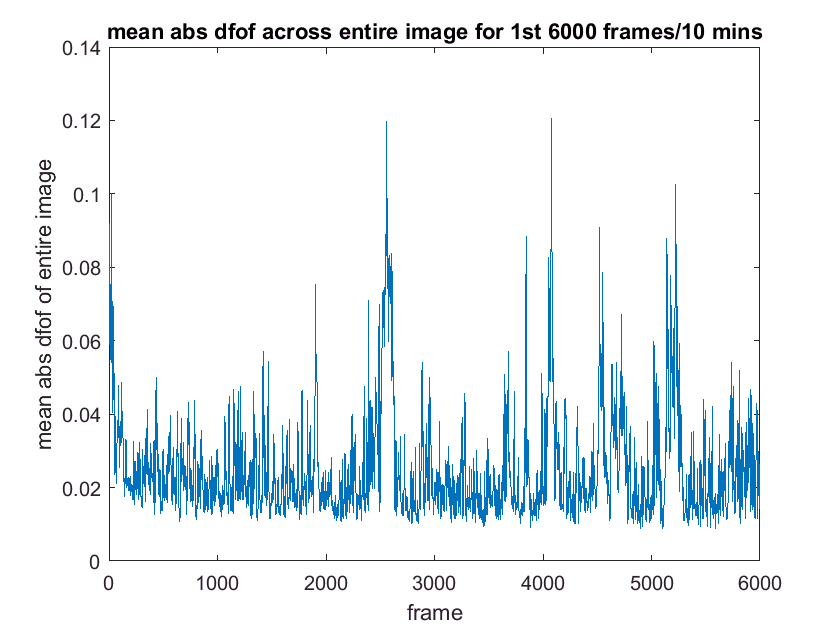

% let's look at that average trace over a time scale closer 
% to our average trial length, ~2,2s / 22 imaging frames

sqMn = squeeze(mn); % getting rid of singletons
trSqMn = sqMn'; % transposing
% select only 111 frames - 111/22 = roughly 5 stim presentations
fiveStimsTrSqMn = trSqMn(1,1:6000);
numFrames4title = length(fiveStimsTrSqMn); 
numMins4title = (numFrames4title/60)/10;

figure
plot(fiveStimsTrSqMn ); 
title(sprintf('mean abs dfof across entire image for 1st %0.00f frames/%0.00f mins',numFrames4title,numMins4title)); 
ylabel('mean abs dfof of entire image') 
xlabel('frame') 
xlim([0 length(fiveStimsTrSqMn)])  

% std gives us a general sense of how much variation there is across all trials
% we also use this to crop in next section

stdMap = std(df(:,:,1:10:end),[],3); % only take every 10 frames (don't need all, why?). taking std across 3rd dimension, time
figure;
colormap jet
imagesc(stdMap,[0 0.1])
title('stDev of dfof_bg across time(downsized)')


[x y] = ginput(2);

df = df(y(1):y(2),x(1):x(2),:); % cropping df to be area I select 

topox_crop = topox(y(1):y(2),x(1):x(2),:);
topoy_crop = topoy(y(1):y(2),x(1):x(2),:);
% crop manually by picking top left and then bottom right corners of a rectangle

stdMap = std(df(:,:,1:10:end),[],3); % gonna show image of std of croppoed df over time
figure
colormap jet
imagesc(stdMap,[0 0.1])
title('Cropped stDev of dfof_bg across time(downsized)') % axes are pixels?



% to make sure our imaging frames are equal intervals apart
frameT = frameT-frameT(1);  %%% time of camera frames;
figure
plot(diff(frameT)) % plotting the difference between each successive value in frameT
title('difference in time between imaging frames')
xlim([0 length(frameT)])
ylim([0 0.7])
xlabel('frame number')
ylabel('seconds')

% savefig('EE8LT_020421_camFrameDiffTime_imThreshPass')

% histogram of dt
hist(diff(frameT))
title('frequency of values for the time difference between imaging frames')
xlabel('seconds between imaging frames')
ylabel('number of frames')


% how many trials over 0.15 Hz and how many under?:
diffFrameT = diff(frameT);
idxFrameToverPt15 = find(diffFrameT>0.15);
idxFrameTunderPt15 = find(diffFrameT<0.15);

% how to find out what stim durs have the slip-ups? 
% maybe when you get to the next script (ConDurAnalysis) and you have
% the durations in order of each trial, for each duration, index into
% the onsets trials at that duration, find the diffFrameT for each trial
% at that duration, take the mean diffFrameT trace over trials, 
% plot that against duration...?

numIdxFrameToverPt15 = length(idxFrameToverPt15);
numIdxFrameTunderPt15 = length(idxFrameTunderPt15);

percentIdxFrameToverPt15 = (numIdxFrameToverPt15/length(frameT))*100
percentIdxFrameTunderPt15 = (numIdxFrameTunderPt15/length(frameT))*100


% same, for allResp

for resp = 1:length(allResp)
    diffResp = diff(allResp(resp).frameT);
    meanDiffResp(resp) = mean(diffResp);
end

figure
clear x_axis
x_axis = [1:length(meanDiffResp)];
plot(x_axis,(meanDiffResp))

xlabel('each stimulus period over one recording sesion')
ylabel('time (in seconds) between frames')
title('difference in time between monitor frames during one recording session')
    
hist(meanDiffResp)
xlabel('seconds between monitor frames')
ylabel('number of frames')

clear idxAllRespOverPt18
clear idxAllRespUnderPt18

idxAllRespOverPt18 = find(meanDiffResp>0.18);
idxAllRespUnderPt18 = find(meanDiffResp<0.18);

numIdxAllRespOverPt18 = length(idxAllRespOverPt18);
numIdxAllRespUnderPt18 = length(idxAllRespUnderPt18);

percentIdxAllRespOverPt18 = (numIdxAllRespOverPt18/length(meanDiffResp))*100
percentIdxAllRespUnderPt18 = (numIdxAllRespUnderPt18/length(meanDiffResp))*100


% histogram of allStop

% stimDetails = information for each condition (rows = trial, column = parameters)

% allStop.frameT = time (in absolute value) of each ISI imaging frame 
% ^ wait or is allStop the time period between when the mouse stops & the stim comes on?
% and normally between that there would also be time spend running/before next stop period 
% and after last response period
% so I guess in our passive version we just don't have the running time period. 
% And I guess identifying and grouping the response & stop periods is something
% doBehavior does on it's own for some reason (rather than us doing it in analysis later)
% update: maybe allStop is *all* the time between the end of a previous response
% and the beginning of the next one.... that would make sense

% So, question - how does matlab/doBehavior identify stop & response sections? 
% frameT, allResp, and allStop all contain a vector where each cell is a frame
% and the values inside the cells are seconds (abs time).
% Is matlab just taking the 
% allResp.frameT = time (in absolute value) of each stim frame, beginning  at 
% whatever frame comes right after the frame where the stim comes on?
% wait is allRes.frameT in monitor frame time (60Hz) and allStop.frameT in imaging time?
% or are they both in monitor time and it's PTSdfof that's in imaging time...

% allStop relates to the imaging frames (10 Hz)
% whereas allResp relates to stimulus frames (60 Hz)

% in both allResp & allStop, frameT is a 1 x # frames during response/sotp period. 
% In the vector, values repeat over multiple cells consecutively, but the do increase 
% overall (should increase at 10 or 60 Hz).
% in allResp, it takes ~57 frames for the cell value to increase by 1. This is close to 60 Hz?
% getting values from 50-80 when i do the same for allStop - seems it should be 
% 60 exactly?

clear onsets

% starting gun - t0 is the first frame a stim comes on (rows in allStop = trials)
% I think allStop is in order of stims presented

%allStop is the time period between mouse stopping and then stim ending (I think)
% its in absolute time taken at the rate/same time as the imaging frames
% so let's take the first imaging frame of the first stopiing time period:
t0 = allStop(1).frameT(1); % maybe this in not 10 Hz its 60 it's just ...
% .. idk the beginning of the trial period I guess/ And it's somewhat randomized 
% how until each stim comes up? is that parameter seperate from meanStop?

% % time of every imaging (? stimulus ?)frame realtive to stim onset (zero being stim onset)

% allResp is abs time at the rate/same time as monitor, 60 Hz
% the number of stop ^ response periods is equal
for i = 1:length(allResp); 
    
    % onset = time of first frame for each stimulus presentation minus of time of first frame 
    % (stim onset relative to first frame when stim comes on) 
    
    % for each reponse period, calculate the value (time) 
    % of each frame relative to the first imaging frame.
    % collect as "time of stim presentation relative to time of 1st 
    % fluorescence image taken after stopping
    onsets(i) = allResp(i).frameT(1)-t0; % only taking frameT(1) - the onset time
    
end % now have onset times for eact stim

% redefine onsets to not include any trials
%that have less than 11 frames before the onset
% of the stim 
idxOnsetsMoreThan10 = find(onsets>10);
%%%%onsets = onsets(idxOnsetsMoreThan10);

% instead of onsets-1, redefine onsets to
% get rid of trials where the trial frame value + 40 
% is larger than the largest onsets value
idxOnsetsCanAdd40 = find(onsets+40<max(onsets));
%%%%onsets = onsets(idxOnsetsCanAdd40);

% for use later to index into only
idxOnsetsMeetBothCriteria = intersect(idxOnsetsMoreThan10,idxOnsetsCanAdd40);
onsets = onsets(idxOnsetsMeetBothCriteria);

% later we take these onset times and get the corrensponding imaging frames
% in frameT, which is it's own seperate variable that I beleive gets stored
% out in the imThreshPass analysis, possibly coming from the maps file,
% which would make sense.


clear onsetDf
clear onsetFrame
clear i

for i = 1:length(onsets); % for each onset time of each stimulus/response period
    % find the imaging frames that come after that onset
    onsetFrame(i) = find(diff(frameT>onsets(i))); % I don't understand the results of the steps on this right hand side of the expression
  
    onsetDf(:,:,:,i) = df(:,:,onsetFrame(i)-11:onsetFrame(i)+40);
   
end



figure
suptitle('avg dfof across all trials, all, conditions, over time')
for f = 1:12; % why 12 - 12 times points just good number for display
    subplot(3,4,f) % each plot is a further point in time
    % Mult time dimesion by 3 times f because we don't want to plot all the
    % frames - notice that we're taking the mean across 4th dimension, so
    % we're taking every 3rd frame averaged across *all* stimulus presnetiations 
    % 11 is because we took 10 frames before stim onset and here we're subtracting onset of stim from baseline
    % baseline is the average activity at each time point across this 5 sec interval that
    % includes pre & post stim onset. the mean activity right after stim
    % onset is subtracted from that baseline
    % wait think I got it - subtracting start of stim from all other time points.. 
    % switches from neg to pos when stim comes on so the baseline is stim onset? 
    % (kinda confused here... we're subtracting the same onset stim point from every 3rd frame... why?
    imagesc(mean(onsetDf(:,:,f*3,:),4)-mean(onsetDf(:,:,11,:),4) ,[-0.01 0.05]) 
    axis equal
    xlabel('pix?') 
    ylabel('pix?') 
end
% savefig('EE8LT_020421_meanDfof_allTrialsCondsOverTime_imThreshPass')


% want to plot a trace just arounf my onset time (+/-), for one 
% representitive point

% show topox topoy crop
figure
subplot(1,2,1);
imshow(topox_crop);
subplot(1,2,2);
imshow(topoy_crop);
title('topox_crop & topoy crop');


% pick 1 pts - V1
clear Onexpts Oneypts 
for i = 1:1
    i
    [Onexpts(i) Oneypts(i)] = ginput(1);
    for s = 1:2
        subplot(1,2,s)
        hold on
        plot(Onexpts(i),Oneypts(i),'*');
    end
end


% plot that point over the peri-stim time period

 % onset df across frames, averaged over trials
 % should give pix x pix x frames (~50 frames, peri-stim)
meanOnsetDfOverTrials = mean(onsetDf,4);

% Now I want to subtract d/f at frame 10 (supposedly bwefore stim onset, 
% at low point in previous trace& 
% from the df/f value from every frame at the point I chose...

% round the point
RoundOneXpts = round(abs(Onexpts));
RoundOneYpts = round(abs(Oneypts));

% let's make a vector that's the same as meanOnsetDfOverTrials but for one point only
% Should return a 1 x frames, possibly need squeeze
sqOnePixMeanOnsetDf = squeeze(meanOnsetDfOverTrials(RoundOneYpts,RoundOneXpts,:))'; % switch x & y. All trials one point
    
% then I want to subtract df/f at the 10th frame from each frame. Should be one 
% cell that equals zero at least

clear i % i = frames 
clear dfRel2Baseline
for i = 1:length(sqOnePixMeanOnsetDf)
    dfRel2Baseline(i) = sqOnePixMeanOnsetDf(i) - sqOnePixMeanOnsetDf(50);
end

x_axis = [1:length(dfRel2Baseline)];
figure
plot(x_axis,dfRel2Baseline)
ylim([-0.005, 0.015])
xlim([0, length(dfRel2Baseline)])

% collecting columns with target & contrast values
for i=1:length(stimDetails); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
    tc(i) = stimDetails(i).targContrast; % making vector with list of targ contrast for each condition
    fc(i) = stimDetails(i).flankContrast;
end

tcTrial = tc(trialCond); % use trial cond to index into correct target contrast value for that condition
fcTrial = fc(trialCond);


range = [0 0.1]; 


% show topox topoy crop
figure
subplot(1,2,1);
imshow(topox_crop);
subplot(1,2,2);
imshow(topoy_crop);
title('topox_crop & topoy crop');


% pick 5 pts - V1, motor ctx, 3 HVAs
clear xpts ypts 
for i = 1:5
    i
    [xpts(i) ypts(i)] = ginput(1);
    for s = 1:2
        subplot(1,2,s)
        hold on
        plot(xpts(i),ypts(i),'*');
    end
end


% % for mouse if imaging cuts out before stim:
% 
% idxOnsetsMeetBothCriteriaAndImgDrop = idxOnsetsMeetBothCriteria(1,1:285)
% 
% clear c
% contrasts = unique(tc); % go thru list of contrasts and take each value only once, make this a new vector
% for c = 1:length(contrasts); % for each unique contrast
%     figure
%     suptitle('dfof every 3rd frame, peri-stim, by target contrast')
% 
%     clear cthTrials
%     cthTcTrialMeetCriteria = tcTrial(idxOnsetsMeetBothCriteriaAndImgDrop);
%     cthTrials = cthTcTrialMeetCriteria==contrasts(c);
%     
%      set(gcf,'Name',sprintf('tc = %0.3f  n = %d',contrasts(c),sum(cthTrials)));
%     for f = 1:12;
%         subplot(3,4,f) 
%         imagesc(mean(onsetDf(:,:,f*3,cthTrials),4)-mean(onsetDf(:,:,11,cthTrials),4) ,range); 
%         hold on; plot(xpts,ypts,'r.')
%         axis equal; axis off;
%     end
% end
% 
% %%% plotting by flanker contrasts - all flanker contrasts are zero so I
% %%% think this plot should be the same as the earlier one that's across all
% contrasts = unique(abs(fc));
% for c = 1:length(contrasts);
%     figure
%     suptitle('dfof every 3rd frame, peri-stim, by flanker contrast')
%     
%     cthTcTrialMeetCriteria = tcTrial(idxOnsetsMeetBothCriteriaAndImgDrop);
%     cthTrials = cthTcTrialMeetCriteria==contrasts(c);
%     
%     set(gcf,'Name',sprintf('fc = %0.3f  n = %d',contrasts(c),sum(cthTrials)));
%     for f = 1:12;
%         subplot(3,4,f)
%         imagesc(mean(onsetDf(:,:,f*3,cthTrials),4)-mean(onsetDf(:,:,11,cthTrials),4) ,range)
%         axis equal; axis off
%     end
% end
% 
% %%% full parameters = flanker and target
% 
% contrasts = unique(abs(fc));
% tcontrasts = unique(tc);
% for c = 1:length(contrasts);
%     for c2= 1:length(tcontrasts)
% % for c = [1 3];
% %     for c2 = [1 3];
% 
%         cthTcTrialMeetCriteria = tcTrial(idxOnsetsMeetBothCriteriaAndImgDrop);
%         cthTrials = cthTcTrialMeetCriteria==contrasts(c);
%         figure
%         suptitle(sprintf('dfof over time both targ & flank, targC = %d', c2))
%         set(gcf,'Name',sprintf('fc = %0.3f tc = %0.3f n = %d',contrasts(c),tcontrasts(c2),sum(cthTrials)));
%         for f = 1:12;
%             subplot(3,4,f)
%             % why median below instead of mean?
%             imagesc(median(onsetDf(:,:,f*3,cthTrials),4)-mean(onsetDf(:,:,11,cthTrials),4) ,range) % what does range mean here
%             axis equal; axis off
%             hold on; 
%             plot(xpts,ypts,'r.'); 
%             colormap jet
%         end
%         % savefig(sprintf('EE8LT_020421_%d_imThreshPass',c2))
%     end
%  end


% FIGS - plotting by target contrast 


% EE81LT needs trials-1 on 010621
    % update: when defining trials in the following loop -
    % tcTrial is a list of all trial conditions, in order.
    % But we don't want to take *all* of the trials at each contrast,
    % we want to leave out the ones that don't meet the criteria set out by the 
    % -10 +40 thing. We can't be indexing trials that are not in onsetDf because they
    % were removed earlier in onsets
    
    % trials is a list of all trial conditions in order for the c-th contrast
    % so let's redefine trials to only include columns (trial numbers)
    % that are equal to the values we used to index into the onset values 
    % that met the -10 +40 criteria (because the onsets is a list of frame 
    % values that are in order of trial)

clear c
contrasts = unique(tc); % go thru list of contrasts and take each value only once, make this a new vector
for c = 1:length(contrasts); % for each unique contrast
    figure
    suptitle('dfof every 3rd frame, peri-stim, by target contrast')
    %% trials =  abs(tcTrial)==contrasts(c); % confused... c-th unique contrast... make abs value of trial target condition equal contrast? then to  'c' contrast, then assign that to trials?
    % EE81LT needs trials-1 on 010621
    % update: conTrials is a list of all trial conditions, in order.
    % But we don't want to take *all* of the trials at each contrast,
    % we want to leave out the ones that don't meet the criteria set out by the 
    % -10 +40 thing. We can't be indexing trials that are not in onsetDf because they
    % were removed earlier in onsets [update: I redefined onsets earlier 
    % so it carried thru to onsetFrame & onsetDf 
    
    % trials is a list of all trial conditions in order for the c-th contrast
    % so let's redefine trials to only include columns that are equal to the values 
    % we used to index into the onset trials that met the -10 +40 criteria
    
    % let's do that by indexing into tcTrials - remember tcTrials are trial 
    % conditions in order of presentation. So if we take the columns that match
    % the trials that met the critera for onsets (which is the length of the 
    % number of trials and contains frame numbers)
    % then wesll have only the trial conditions for those trials that emt the criteria
    clear cthTrials
    cthTcTrialMeetCriteria = tcTrial(idxOnsetsMeetBothCriteria);
    cthTrials = cthTcTrialMeetCriteria==contrasts(c);
    
     set(gcf,'Name',sprintf('tc = %0.3f  n = %d',contrasts(c),sum(cthTrials)));
    for f = 1:12;
        subplot(3,4,f) 
        imagesc(mean(onsetDf(:,:,f*3,cthTrials),4)-mean(onsetDf(:,:,11,cthTrials),4) ,range); 
        hold on; plot(xpts,ypts,'r.')
        axis equal; axis off;
    end
end


%%% plotting by flanker contrasts - all flanker contrasts are zero so I
%%% think this plot should be the same as the earlier one that's across all
clear c
contrasts = unique(abs(fc));
for c = 1:length(contrasts);
    figure
    suptitle('dfof every 3rd frame, peri-stim, by flanker contrast')
    
    cthTcTrialMeetCriteria = tcTrial(idxOnsetsMeetBothCriteria);
    cthTrials = cthTcTrialMeetCriteria==contrasts(c);
    
    set(gcf,'Name',sprintf('fc = %0.3f  n = %d',contrasts(c),sum(cthTrials)));
    for f = 1:12;
        subplot(3,4,f)
        imagesc(mean(onsetDf(:,:,f*3,cthTrials),4)-mean(onsetDf(:,:,11,cthTrials),4) ,range)
        axis equal; axis off
    end
end


%%% full parameters = flanker and target

clear c

contrasts = unique(abs(fc));
tcontrasts = unique(tc);
for c = 1:length(contrasts);
    for c2= 1:length(tcontrasts)
% for c = [1 3];
%     for c2 = [1 3];

        cthTcTrialMeetCriteria = tcTrial(idxOnsetsMeetBothCriteria);
        cthTrials = cthTcTrialMeetCriteria==contrasts(c);
        figure
        suptitle(sprintf('dfof over time both targ & flank, targC = %d', c2))
        set(gcf,'Name',sprintf('fc = %0.3f tc = %0.3f n = %d',contrasts(c),tcontrasts(c2),sum(cthTrials)));
        for f = 1:12;
            subplot(3,4,f)
            % why median below instead of mean?
            imagesc(median(onsetDf(:,:,f*3,cthTrials),4)-mean(onsetDf(:,:,11,cthTrials),4) ,range) % what does range mean here
            axis equal; axis off
            hold on; 
            plot(xpts,ypts,'r.'); 
            colormap jet
        end
        % savefig(sprintf('EE8LT_020421_%d_imThreshPass',c2))
    end
end


figure
suptitle('picked points')

subplot(1,2,1);
imshow(topox_crop); 
hold on; 
plot(xpts,ypts,'wo')

subplot(1,2,2);
imshow(topoy_crop);
hold on; 
plot(xpts,ypts,'wo')

% savefig('277RT_020421_picked_points')


%% save('041121_277RT_imThreshPass_Vars_idxMeetBothCriteria','idxOnsetsMeetBothCriteria')
% save('041021_277RT_imThreshPass_Vars','xpts','ypts','onsetDf','stimDetails','idxOnsetsMeetBothCriteria','df','topox','topoy','allResp','allStop','trialCond')
% save('277RT_020421_imThreshPass','xpts','ypts','onsetDf','stimDetails','df','topox','topoy','allResp','allStop','trialCond')
% save('277RT_031121_imThreshPass','xpts','ypts','onsetDf','stimDetails','idxOnsetsMeetBothCriteria','df','topox','topoy','allResp','allStop','trialCond')
% save('EE81LT_040221_imThreshPass_misnamed','xpts','ypts','onsetDf','stimDetails','idxOnsetsMeetBothCriteriaAndImgDrop','df','topox','topoy','allResp','allStop','trialCond')
% save('EE81LT_040421_imThreshPass_misnamed','xpts','ypts','onsetDf','stimDetails','idxOnsetsMeetBothCriteria','df','topox','topoy','allResp','allStop','trialCond')